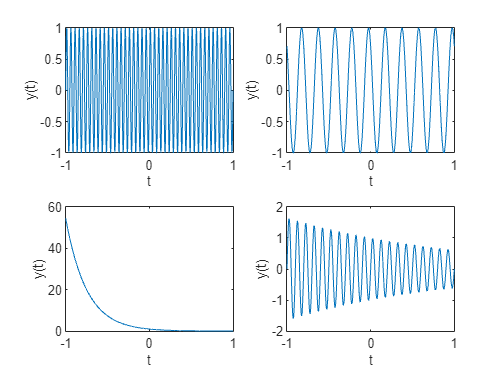

a=1+mod(256,3);
t=-1:0.001:1;
y1=sin(20*pi*a*t);
subplot(2,2,1)
plot(t,y1)
y2=cos(5*pi*a*t+(pi/4));
subplot(2,2,2)
plot(t,y2)
y3=exp(-2*a*t);
subplot(2,2,3)
plot(t,y3)
y4=exp(-0.25*a*t).*(sin(20*pi*t));
subplot(2,2,4)
plot(t,y4)

subplot(2,2,1)
xlabel("t")

subplot(2,2,2)
ylabel("y(t)")
subplot(2,2,4)

subplot(2,2,1)

subplot(2,2,2)
xlabel("t")

subplot(2,2,1)
ylabel("y(t)")

subplot(2,2,3)
xlim([-1.00 1.00])
ylim([0 60])
xlabel("t")
ylabel("y(t)")
subplot(2,2,4)
xlabel("t")
ylabel("y(t)")

a=1+mod(256,3);
t=-5:0.001:5;
x=exp(-a*t)

x = 1.0e+04 *

    2.2026    2.1982    2.1939    2.1895    2.1851    2.1807    2.1764    2.1720    2.1677    2.1634    2.1590    2.1547    2.1504    2.1461    2.1418    2.1375    2.1333    2.1290    2.1248    2.1205    2.1163    2.1121    2.1078    2.1036    2.0994    2.0952    2.0910    2.0869    2.0827    2.0785    2.0744    2.0702    2.0661    2.0620    2.0578    2.0537    2.0496    2.0455    2.0414    2.0374    2.0333    2.0292    2.0252    2.0211    2.0171    2.0131    2.0090    2.0050    2.0010    1.9970


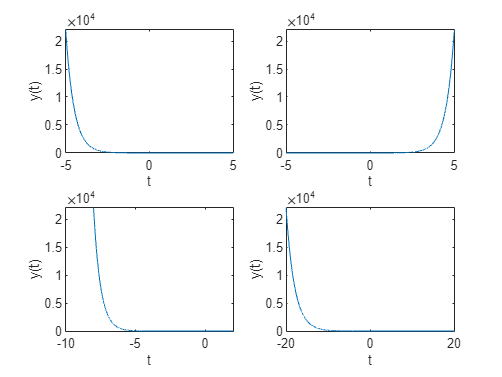

subplot(2,2,1)
plot(t,x)
subplot(2,2,2)
plot(-t,x)
subplot(2,2,3)
plot(t-(1.5*a),x)
subplot(2,2,4)
plot(2*a*t,x)

subplot(2,2,1)
xlabel("t")
ylabel("y(t)")
subplot(2,2,2)
xlabel("t")
ylabel("y(t)")
subplot(2,2,3)
xlabel("t")
ylabel("y(t)")
subplot(2,2,4)
xlabel("t")
ylabel("y(t)")

ecg=load("ECG_Data.txt")

ecg =     0.2284
    0.2240
    0.2206
    0.2163
    0.2111
    0.2059
    0.1998
    0.1964
    0.1938
    0.1886


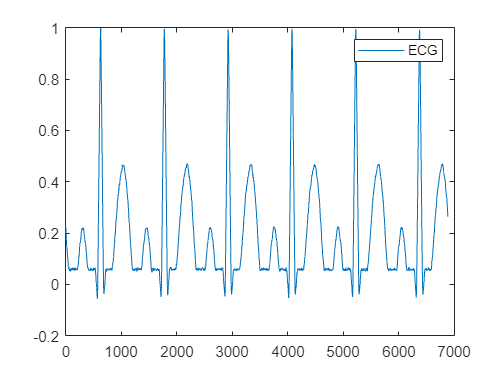

subplot(1,1,1)
plot(ecg)
% 'C:\Users\SNEHA SRI\Documents\MATLAB\New Folder\Experiment-1\Experiment-1'
legend("ECG")

jan_rain=load("RainFallIndia_Jan.txt")

jan_rain =   107.3000
   43.7000
   32.7000
   42.2000
   33.3000
   28.0000
   42.2000
   42.2000
   83.7000
   70.3000


nbins=5

nbins = 5

histogram(jan_rain,nbins)
hold on
july_rain=load("RainFallIndia_July.txt")

july_rain = 1.0e+03 *

    0.2850
    0.4213
    0.4654
    0.6601
    0.9909
    0.2174
    0.8519
    0.6601
    0.2720
    0.4608


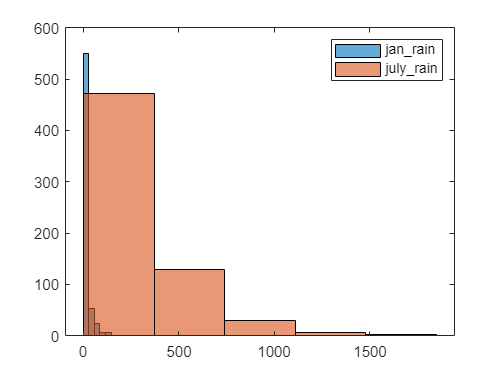

histogram(july_rain,nbins)
hold off

legend("show")

m=[jan_rain;july_rain]

m = 1.0e+03 *

    0.1073
    0.0437
    0.0327
    0.0422
    0.0333
    0.0280
    0.0422
    0.0422
    0.0837
    0.0703


mean(m)

ans = 172.2224

std(m)

ans = 220.0828

[y,Fs]=audioread('C:\Users\SNEHA SRI\Documents\MATLAB\New Folder\Experiment-1\Experiment-1\Track001.wav')

y =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


Fs = 44100

sound(y,Fs)

% % Load the speech signal from the WAV file
% [s, fs] = audioread('speech.wav');
% 
% % Plot the original speech signal
% figure;
% t = (0:length(s)-1) / fs;
% subplot(2, 1, 1);
% plot(t, s);
% title('Original Speech Signal');
% xlabel('Time (s)');
% ylabel('Amplitude');
% 
% % Define the user-defined function to generate y(n)
% function y = generate_y(signal, F, fs)
%     F = 250 * 2;
%     y = signal .* cos(2 * pi * F  / fs);
% end
% 
% % Choose a value for F (e.g., 250 * alpha Hz)
% 
% 
% % Generate y(n)
% y = generate_y(s, F, fs);
% 
% % Plot y(n)
% subplot(2, 1, 2);
% plot(t, y);
% title('Generated y(n)');
% xlabel('Time (s)');
% ylabel('Amplitude');
% 
% % Analytical computation of the Fourier transform
% f = -fs/2 : fs/length(s) : fs/2 - fs/length(s);
% S = fftshift(fft(s));
% Y = (1/2) * (S .* exp(-1j * 2 * pi * F * t.') + conj(S) .* exp(1j * 2 * pi * F * t.'));
% Y = fftshift(Y);
% 
% % Plot the spectrum of the signals
% figure;
% subplot(2, 1, 1);
% plot(f, abs(S));
% title('Spectrum of Original Speech Signal');
% xlabel('Frequency (Hz)');
% ylabel('Magnitude');
% 
% subplot(2, 1, 2);
% plot(f, abs(Y));
% title('Spectrum of Generated y(n)');
% xlabel('Frequency (Hz)');
% ylabel('Magnitude');

fs = 5000; % Sampling frequency in Hz (time resolution of 0.001s)
t = 0:0.001:4.999; % Time vector from 0 to 4.999 seconds

% Frequency values
alpha = 2.0; % Adjust as needed
f1 = 200 * alpha; % Frequency of the first sinusoid (200α Hz)
f2 = 220 * alpha; % Frequency of the second sinusoid (220α Hz)

% Generate the sinusoids
sinusoid1 = sin(2 * pi * f1 * t);
sinusoid2 = sin(2 * pi * f2 * t);

% Combine the sinusoids
combined_signal = sinusoid1 + sinusoid2;

% Normalize the signal to the range [-1, 1]
combined_signal = combined_signal / max(abs(combined_signal));

% Write the combined signal to a .wav file
audiowrite('combined_sinusoids.wav', combined_signal, fs);

% Listen to the combined signal
sound(combined_signal, fs);

fs = 44100; % Sampling frequency in Hz
t = 0:1/fs:1.5; % Time vector for each note (1.5 seconds per note)

% Frequencies for each note (Do, Re, Mi, Fa, So, La, Ti, Do)
frequencies = [261.63, 293.66, 329.63, 349.23, 392.00, 440.00, 493.88, 523.25];

% Initialize an empty signal
combined_signal = zeros(1, length(t) * length(frequencies));

% Generate and append the sinusoidal signals for each note
for i = 1:length(frequencies)
    note_signal = sin(2 * pi * frequencies(i) * t);
    combined_signal(1, (i - 1) * length(t) + 1 : i * length(t)) = note_signal;
end

% Normalize the signal to the range [-1, 1]
combined_signal = combined_signal / max(abs(combined_signal));

% Write the combined signal to a .wav file
audiowrite('melody_sequence.wav', combined_signal, fs);
sound(combined_signal, fs);

textData=load("ConvFile2.txt")

textData =     0.0000
   -0.0000
   -0.0001
   -0.0001
   -0.0002
   -0.0002
   -0.0003
   -0.0003
   -0.0003
   -0.0003


[y,Fs]=audioread('Track003.wav')

y =     0.1351
    0.1443
    0.1452
    0.1451
    0.1652
    0.1836
    0.1632
    0.1314
    0.1407
    0.1778


Fs = 44100

% sound(y,Fs)
normalizedText = textData / max(abs(textData));
convolution_result = conv(y,normalizedText);

% Display the convolution result
disp('Convolution Result:');

Convolution Result:


disp(convolution_result);

    0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0001
   -0.0001
   -0.0001
   -0.0002
   -0.0003
   -0.0003
   -0.0004
   -0.0004
   -0.0004
   -0.0005
   -0.0005
   -0.0005
   -0.0005
   -0.0005
   -0.0004
   -0.0003
   -0.0003
   -0.0002
   -0.0001
    0.0000
    0.0001
    0.0002
    0.0003
    0.0003
    0.0003
    0.0003
    0.0003
    0.0002
    0.0001
   -0.0001
   -0.0003
   -0.0005
   -0.0007
   -0.0010
   -0.0012
   -0.0014
   -0.0016
   -0.0017
   -0.0017
   -0.0017
   -0.0015
   -0.0013
   -0.0010
   -0.0006
   -0.0002
    0.0003
    0.0008
    0.0013
    0.0017
    0.0021
    0.0025
    0.0027
    0.0028
    0.0028
    0.0025
    0.0021
    0.0016
    0.0008
   -0.0001
   -0.0011
   -0.0021
   -0.0032
   -0.0043
   -0.0053
   -0.0061
   -0.0067
   -0.0070
   -0.0071
   -0.0067
   -0.0060
   -0.0049
   -0.0034
   -0.0016
    0.0005
    0.0029
    0.0053
    0.0078
    0.0102
    0.0123
    0.0140
    0.0151
    0.0156
    0.0152
    0.0140
    0.0117
    0.0083
    0.0038

audiowrite('convolution_result.wav', convolution_result, fs);
[soun,Fs]=audioread('convolution_result.wav')

soun =          0
   -0.0000
   -0.0000
   -0.0001
   -0.0001
   -0.0001
   -0.0002
   -0.0002
   -0.0003
   -0.0003


Fs = 44100

sound(soun,Fs)




